Variable force: The effect of increasing the initial force component (F) is an exponential increase trend in displacement which is consistent with the physics of a moving pendulum with friction. With a large force applied to the system, pendulum will swing back and forth a greater number of times before eventually being halted by the bleeding of energy due to friction. This explanation can be seen in the figure below where the total displacement of the system is increasing with the amount of initial force applied.

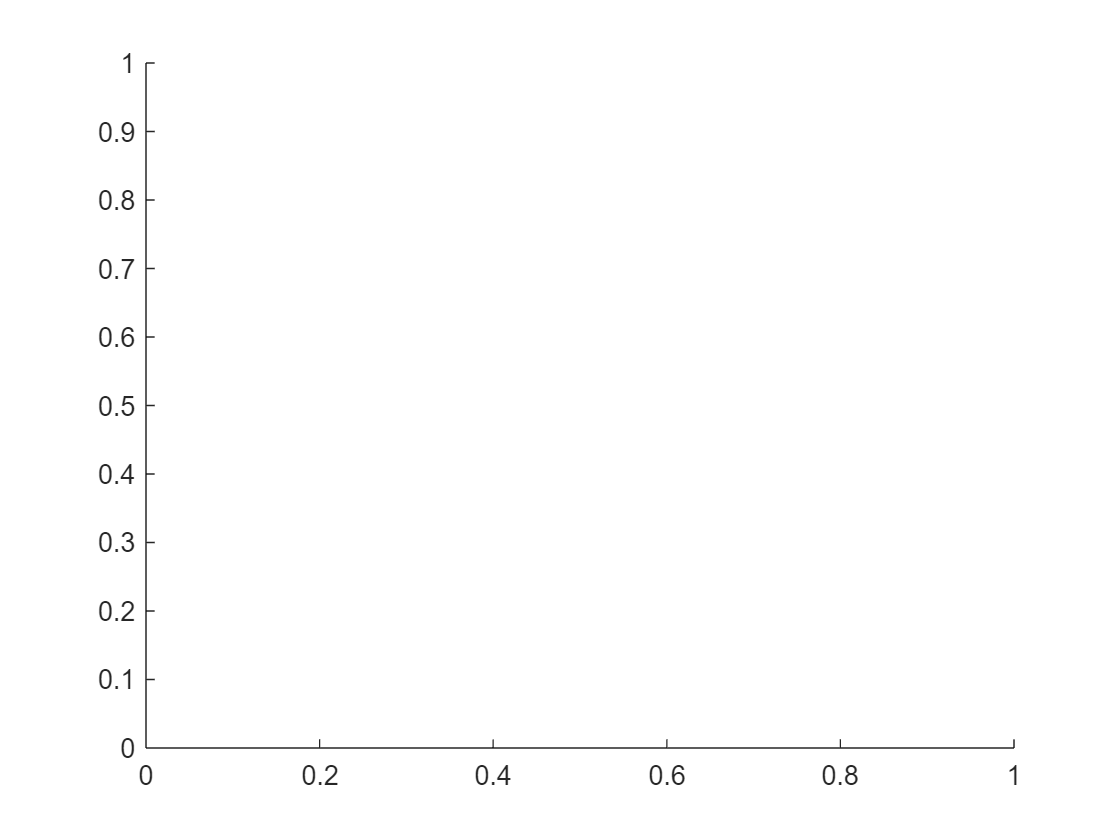

time_t = 0:0.001:10;
IP = InvertedPendulum();
%V0 = [0;0; -0.175;0]; % initial bar tilt 10 degrees
V0 = [0;0; 0;0];
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];
figure(Name='Initial Force Comparison')
hold on

sr = IP.euler_method(V0, 5, time=time_t, description='large force', lqr=true,N=[1;0;0;0], ...
    Q=Q);

Execution of script lqr as a function is not supported:
C:\Users\Kevin\OneDrive\Documents\Math 340\Math340FinalProject\lqr.mlx

Error in InvertedPendulum/euler_method (line 79)
                [K, s, p] = lqr(obj.A, obj.B, Q, R, N);

sr.plotX
sr2 = IP.euler_method(V0, 0.25, time=time_t, description='small force', lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr2.plotX
sr3 = IP.euler_method(V0, 2, time=time_t, description='medium force', lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr3.plotX
hold off
legend

friction variable: Friction is a force that dissipates energy from the system. The result is a net loss in displacement when constant friction is present. 

This principle is demonstrated in the figure below where the absolute displacement of the system is decreasing with increasing friction (b). Friction is also a stabilizing force because its vector is negative relative to the origin of motion and scales with the initial force. The linear approximation uses a constant friction force for each example.

clf;
time_t = 0:0.001:10;
IP = InvertedPendulum();
IP2 = InvertedPendulum(b=0.5);
IP3 = InvertedPendulum(b=1);
%V0 = [0;0; -0.175;0]; % initial bar tilt 10 degrees
V0 = [0;0; 0;0];
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];
hold on
sr = IP.euler_method(V0, 5, time=time_t, description="low friction", lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr.plotX
sr2 = IP2.euler_method(V0, 5, time=time_t, description="medium friction", lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr2.plotX
sr3 = IP3.euler_method(V0, 5, time=time_t, description="high friction", lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr3.plotX
hold off
legend

Variable Cart Mass: The moment of inertia is one of the most important variables to consider when analyzing a moving body because it dictates an object's relative resistance to motion. The absolute moment of inertia increases with the mass of an object according to the torque equation where $T=-L\left(\textrm{mgsin}\left(\theta \right)\right)$. The negative sign indicates that the torque acts on the opposite side of the angular displacement. The equation can be rewritten as $I\alpha =-L\left(\textrm{mgsin}\left(\theta \right)\right)$. Upon analysis of the cart below, the total displacement of the pendulum is decreasing with increasing cart mass which is consistenent with an increasing moment of inertia.

clf;
time_t = 0:0.001:10;
IP = InvertedPendulum();
IP2 = InvertedPendulum(M=0.75);
IP3 = InvertedPendulum(M=1);
%V0 = [0;0; -0.175;0]; % initial bar tilt 10 degrees
V0 = [0;0; 0;0];
hold on
sr = IP.euler_method(V0, 5, time=time_t, description="Low mass cart", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr.plotX
sr2 = IP2.euler_method(V0, 5, time=time_t, description="Medium mass cart", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr2.plotX
sr3 = IP3.euler_method(V0, 5, time=time_t, description="High mass cart", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr3.plotX
hold off
legend

Variable initial pendulum position: The initial position of the pendulum is important because of gravitation potential energy whereby the further the angle the pendulum starts from its equilibrium point the more potential energy is contained within the system initially. The trend in the figure below clearly indicates a greater amount of displacement is observed in the pendulum with increasing potential energy.

clf;
time_t = 0:0.001:10;
IP = InvertedPendulum();
%V0 = [0;0; -0.175;0]; % initial bar tilt 10 degrees
V01 = [0;0;0;0];
V02 = [0;0;-0.349;0];
V03 = [0;0;-0.785;0];
V04 = [0;0;-1.047;0];
V05 = [0;0;-1.571;0];
hold on
sr = IP.euler_method(V01, 5, time=time_t, description="0 degrees", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr.plotX
sr2 = IP.euler_method(V02, 5, time=time_t, description="20 degrees", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr2.plotX
sr3 = IP.euler_method(V03, 5, time=time_t, description="45 degrees", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr3.plotX
sr4 = IP.euler_method(V04, 5, time=time_t, description="60 degrees", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr4.plotX
sr5 = IP.euler_method(V05, 5, time=time_t, description="90 degrees", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr5.plotX
hold off
legend

Scaler multiples of LQR matrix: The control matrix provides a stabilizing effect on the pendulum like friction. As the control matrix was scaled with non zero components and constant initial values, the total displacement was reduced indicating the control matrix acts similar to a dampening force like friction in the figure above. This same trend is visible in the proceeding figure where all diagonal components of the LQR are set to constant values and scaled. Using an LQR with all diagonal components included, the total displacement appears to dampened by the same magnitude, but instead a higher percentage of the total pendulum displacement is in the negative direction.

clf;
time_t = 0:0.001:10;
V0 = [0;0;0;0];
Q=  [1 0 0 0;
    0 0 0 0;
    0 0 1 0;
    0 0 0 0];

Q1= [2 0 0 0;
    0 0 0 0;
    0 0 2 0;
    0 0 0 0];

Q2= [4 0 0 0;
    0 0 0 0;
    0 0 4 0;
    0 0 0 0];

Q3= [3 0 0 0;
    0 0 0 0;
    0 0 3 0;
    0 0 0 0];

Q4= [5 0 0 0;
    0 0 0 0;
    0 0 5 0;
    0 0 0 0];
IP = InvertedPendulum();
hold on
sr = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q, description='default Q');
sr.plotX;
sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
     Q=Q1, description='2 times scaled Q');
sr2.plotX
sr3 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q2, description='4 times Q');
sr3.plotX
sr4 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q3, description='3 times scaled Q');
sr4.plotX
sr5 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q4, description='5 times scaled Q');
sr5.plotX
hold off
legend()
clf;
hold on
sr.plotdC;
sr2.plotdC;
sr3.plotdC;
sr4.plotdC;
sr5.plotdC;
hold off
xlim([-0.1 0.1]);
legend()


clf;
hold on
sr.plotdC(cumulative=false);
sr2.plotdC(cumulative=false);
%sr3.plotdC(cumulative=true);
%sr4.plotdC(cumulative=true);
%sr5.plotdC(cumulative=true);
hold off
legend()
xlim([-0.1 0.1])

Q matrix with all variables included and scaled See above explanation: 

clf;
time_t = 0:0.001:10;
Q=  [1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];

Q1= [2 0 0 0;
    0 2 0 0;
    0 0 2 0;
    0 0 0 2];

Q2= [4 0 0 0;
    0 4 0 0;
    0 0 4 0;
    0 0 0 4];

Q3= [3 0 0 0;
    0 3 0 0;
    0 0 3 0;
    0 0 0 3];

Q4= [5 0 0 0;
    0 5 0 0;
    0 0 5 0;
    0 0 0 5];
IP = InvertedPendulum();
hold on
sr = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q, description='default Q');
sr.plotX;
sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
     Q=Q1, description='2 times scaled Q');
sr2.plotX
sr3 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q2, description='4 times Q');
sr3.plotX
sr4 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q3, description='3 times scaled Q');
sr4.plotX
sr5 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q4, description='5 times scaled Q');
sr5.plotX
hold off
legend()

Q matrix wtih different ratios of displacement (x) to phi and x' to phi': By observing the displacement graph it is clear that the displacement vector is not affected greatly by the angle of phi even when the value of phi is very large compared to displacement in ratio. This is does make sense since phi is only an angle of the starting point of the bar and there for will eventually go to equilbrium depending on the force applied. When the displacement value in the LQR matrix was scaled up, the overall displacement was reduced. The opposite effect can be seen when scaling up the angle phi, but the magnitude of difference in displacement of caused by phi appears fairly negligible. It's possible that this scaling issue arises from the fact that the units of phi are in radians and units of displacement are in meters.

clf;
time_t = 0:0.001:10;
Q=  [1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];

Q1= [1 0 0 0;
    0 1 0 0;
    0 0 2 0;
    0 0 0 1];

Q2= [2 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];

Q3= [3 0 0 0;
    0 1 0 0;
    0 0 2 0;
    0 0 0 1];

Q4= [2 0 0 0;
    0 1 0 0;
    0 0 3 0;
    0 0 0 1];

Q5= [1 0 0 0;
    0 100 0 0;
    0 0 1 0;
    0 0 0 100];

Q6= [1 0 0 0;
    0 50 0 0;
    0 0 1 0;
    0 0 0 100];

Q7= [1 0 0 0;
    0 100 0 0;
    0 0 1 0;
    0 0 0 50];
IP = InvertedPendulum();
hold on
sr = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q, description='1 to 1 ratio');
sr.plotX;
sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
     Q=Q1, description='1 to 2 ratio');
sr2.plotX
sr3 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q2, description='2 to 1 ratio');
sr3.plotX
sr4 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q3, description='3 to 2 ratio');
sr4.plotX
sr5 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q4, description='2 to 3 ratio');
sr5.plotX
sr6 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q5, description='100 x prime and 100 phi prime');
sr6.plotX
sr7 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q6, description='50 x prime  and 100 phi prime');
sr7.plotX
sr8 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q7, description='100 x prime  and 50 phi prime');
sr8.plotX
hold off
legend()
clf;
hold on
sr.plotdC;
sr2.plotdC;
sr3.plotdC;
sr4.plotdC;
sr5.plotdC;
hold off
xlim([-0.1 0.1]);
legend()

With and Without LQR matrix:

The system is unstable without the LQR matrix present. The result of the LQR matrix being absent is that the pendulum’s displacement will increase to infinity in the negative directrion. If you do not have the LQR, you violate the assumptions of the model which dictate that the angle of phi is small. 

clf;
time_t = 0:0.001:10;
IP = InvertedPendulum();
%V0 = [0;0; -0.175;0]; % initial bar tilt 10 degrees
V0 = [0;0; 0;0];
Force = 5;
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];
figure(Name='Initial Force Comparison')
hold on
sr = IP.euler_method(V0, 5, time=time_t, description='With LQR', lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr.plotX
sr2 = IP.euler_method(V0, 5, time=time_t, description='Without LQR', lqr=false,N=[1;0;0;0], ...
    Q=Q);
sr2.plotX
hold off 
legend()
xlim([0,1])